# Figure 2G

**Load Data**

clear
[file_loc] = fileparts(matlab.desktop.editor.getActiveFilename);
cd(file_loc);
dataDir = '..\..\FINAL DATA files';

load([dataDir filesep 'A008_data.mat'],'S','settings','allIF');

conditions = settings.conditions

conditions = 4×5 cell array
    {'siControl DMSO'}    {[  3]}    {[    3 4 5 6]}    {[1]}    {[0 0 0]}
    {'siControl 4/6i'}    {[  3]}    {[7 8 9 10 11]}    {[1]}    {[0 0 0]}
    {'siCdh1 DMSO'   }    {[4 5]}    {[    3 4 5 6]}    {[1]}    {[0 0 0]}
    {'siCdh1 4/6i'   }    {[4 5]}    {[7 8 9 10 11]}    {[1]}    {[0 0 0]}

framesPerHr = 60/12;
frameDrugAdded = 0;
frameEdU = 0;
timeStart = 0;

folding =5;

numFrames = size(S(1).area,2);
xFrames = 1:numFrames;
xTime = (xFrames-1)./framesPerHr;

times = arrayfun(@(x)(numFrames - x.POI)/framesPerHr,S,'UniformOutput',false);
[S.POI_time] = times{:};

for i = 1:length(S)
    S(i).POI_realtime = S(i).POI/framesPerHr;
    S(i).POI_drug_time = (frameDrugAdded - S(i).POI)/framesPerHr;
end

**Gate cells**

for i = 1:length(S)
    dat = S(i);

    crlGate = false(length(dat.POI(:,3)),1);
    for n = 1:length(dat.POI(:,3))

         if dat.POI(n,3) + round(4*framesPerHr) <= numFrames & dat.POI(n,3) - round(1*framesPerHr) > 0
            crlGate(n) = dat.crlNormAct(n,dat.POI(n,3) + round(4* framesPerHr)) < .3 &...
            nanmean(dat.crlNormAct(n,dat.POI(n,3) + [-1* framesPerHr: -.5* framesPerHr] )) > .5;
        end

         if dat.POI(n,1) + round(5*framesPerHr) <= numFrames 
            cdkHighGate(n) = dat.cdk(n,dat.POI(n,1) + round(5* framesPerHr)) > .5;
         end

    end


    S(i).crlGate = crlGate;

end 

numcell = 4363

numcell = 3258

numcell = 1712

numcell = 3265

numcell = 2065

numcell = 248

numcell = 1910

numcell = 594

numcell = 3259

numcell = 1560

numcell = 2603

numcell = 568

numcell = 639

numcell = 658

numcell = 842

numcell = 4401

numcell = 2067

numcell = 2030

numcell = 3294

numcell = 2718

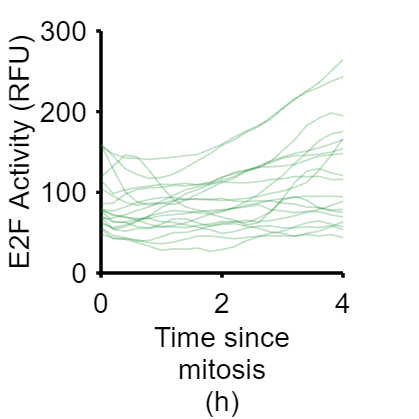

numcell = 640

numcell = 4068

numcell = 2043

numcell = 4169

numcell = 594

numcell = 598

numcell = 2960

numcell = 1783

numcell = 2025

numcell = 2858

numcell = 3862

numcell = 638

numcell = 799

numcell = 796

numcell = 2603

numcell = 1937

numcell = 644

numcell = 4287

numcell = 692

numcell = 4361

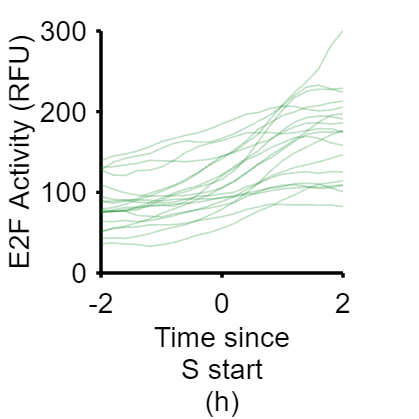

conds=[1];
poiAlign = [ 1 3];
alignNames = {'mitosis','S start'};
xlimits = {[0 4],[-2 2],[-6 8]};
for p = 1:length(poiAlign)
 figure('units','inches','position',[0 0 4 4]), hold on
    for i=1:length(conds)
    
        inds = ~isnan(S(conds(i)).POI(:,poiAlign(p))) & S(conds(i)).goodCdk &...
           S(conds(i)).POI(:,3)>80 & S(conds(i)).POI(:,3)<100 & S(conds(i)).crlGate & S(conds(i)).sigNuc(:,10)>30 ;
        cells = find(inds);
        for numcell = randsample(cells,min([20 length(cells)]))'
            numcell
            timeAligned = xTime-S(conds(i)).POI(numcell,poiAlign(p))/framesPerHr;
            align_val = S(conds(i)).POI(numcell,poiAlign(p));
          
            start = S(conds(i)).POI(numcell,1) + 2;
          
            subplot(1,length(conds),i),hold on
            patchline(timeAligned,nansmooth(S(conds(i)).sigNuc(numcell,:)+30,3),...
                'edgecolor',[0 .5 .1],'linewidth',1,'edgealpha',0.25);
            ylabel('E2F Activity (RFU)');
            ylim([0 300]);
            yticks([0:100:300])
            xlim(xlimits{p});
            xlabel(['Time since' alignNames(p) '(h)']);
            axis square
            set(gca,'linewidth',2,'fontsize',17)
           
        end
    end
      % print_pdf(['fig_2g',num2str(p),'.pdf'])
end